close all; clear all;

load('cmap_mat.mat');
tif_PathName=('C:\Users\Stav\Desktop\school\2\Research\hohoba\trimSegment&Featuers\images\Mosaics\Sde_David_2022-06-29_FLIR')

tif_PathName = 'C:\Users\Stav\Desktop\school\2\Research\hohoba\trimSegment&Featuers\images\Mosaics\Sde_David_2022-06-29_FLIR'

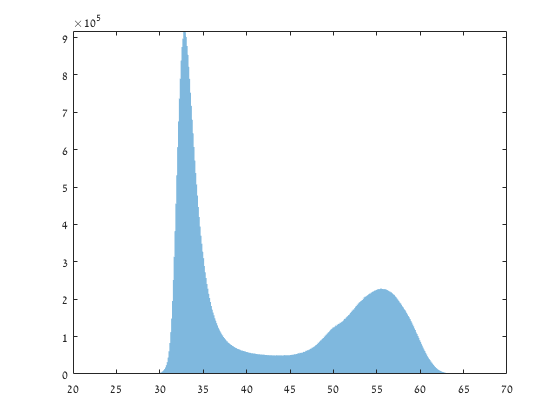

TIR=imread("Sde_David_2022-06-29_FLIR.tif");
tfw_file=strcat("Sde_David_2022-06-29_FLIR.tfw");
tfw=worldfileread(tfw_file,'planar',size(TIR));
TIR= double(TIR);
TIR(find(TIR<0.1))=0;
TIR(find(TIR>70))=0;
histogram(TIR(:),'BinWidth', 0.1,'BinLimits', [20 70],'FaceAlpha',0.5,'EdgeColor','none');
axis tight

%% open tif file with geographic coordinates


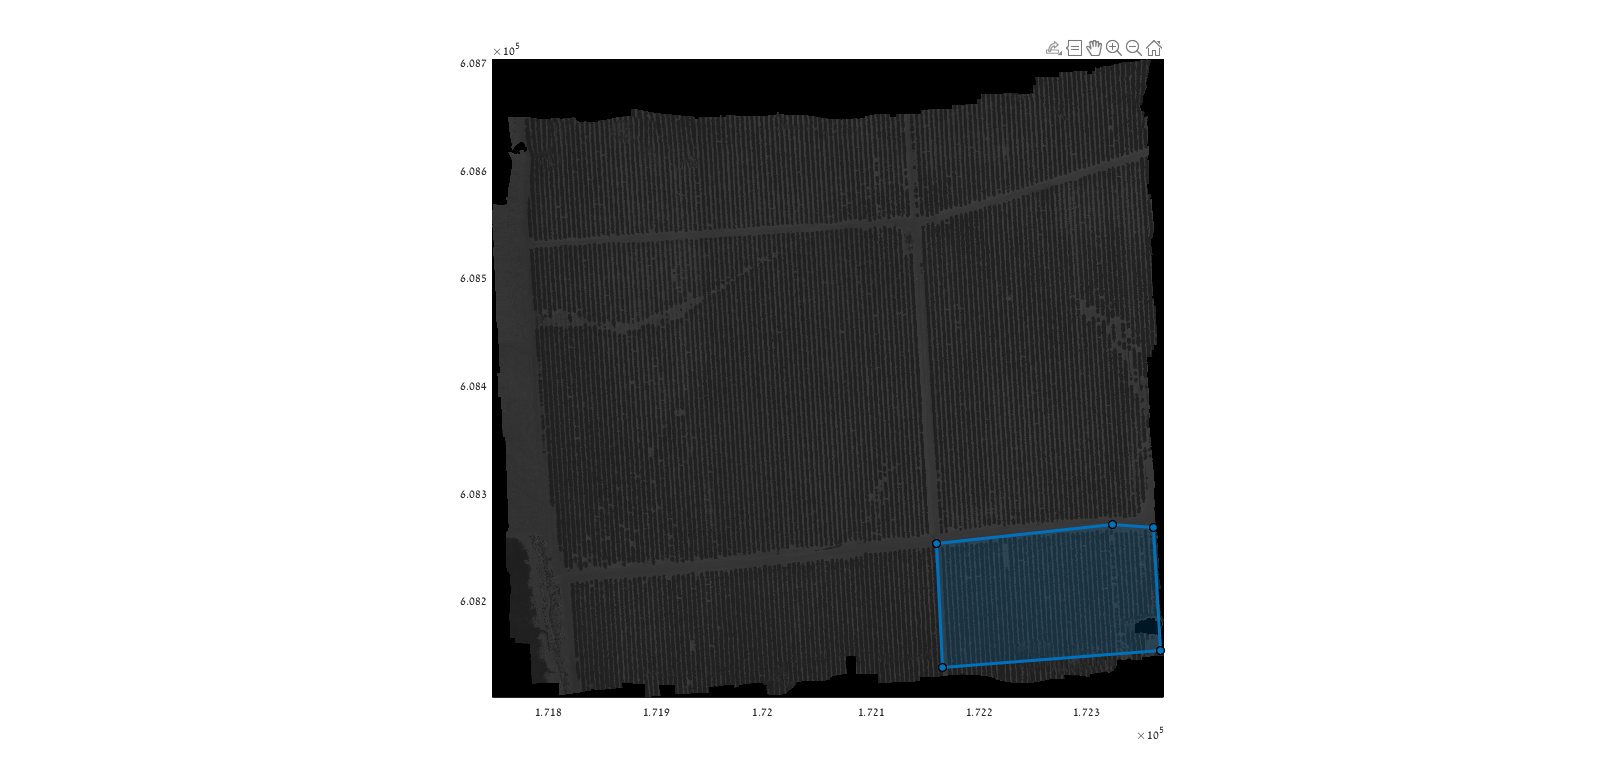

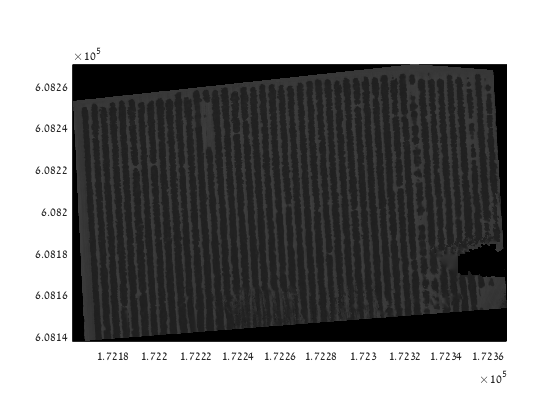

[tir_mask,trim_tfw,corr_vec]=trim_tif_twf(tfw,TIR,tif_PathName);

Name= 'plot_f'

Name = 'plot_f'

save_path='C:\Users\Stav\Desktop\school\2\Research\hohoba\results\plot\';
worldfilewrite(trim_tfw, [save_path  Name '.tfw']);
save([save_path  Name '.mat'],'tir_mask');
imwrite(tir_mask, [save_path  Name '.png']);

trim imag

function [tif_mask,trim_tfw,corr_vec]=trim_tif_twf(tfw,tif,tif_PathName)
% trim tif image
h=figure;
mapshow(uint8(tif),tfw);
xlim(tfw.XLimWorld);ylim(tfw.YLimWorld);
hold on
figure(h);
hp = drawpolygon;
pos_map=hp.Position;
[row_pos_pix,col_pos_pix]=map2pix(tfw,pos_map);

X_upper_pix=round(min(col_pos_pix));
Y_upper_pix=round(min(row_pos_pix));
X_lower_pix=round(max(col_pos_pix));
Y_lower_pix=round(max(row_pos_pix));

[X_upper_map,Y_upper_map]=pix2map(tfw,Y_upper_pix,X_upper_pix);
[X_lower_map,Y_lower_map]=pix2map(tfw,Y_lower_pix,X_lower_pix);

min_X_map=min([X_lower_map,X_upper_map]);
max_X_map=max([X_lower_map,X_upper_map]);
min_Y_map=min([Y_lower_map,Y_upper_map]);
max_Y_map=max([Y_lower_map,Y_upper_map]);

corr_vec=[min_X_map max_X_map min_Y_map max_Y_map];

% trim tfw image
trim_tfw =worldfileread([tif_PathName '.tfw']);
trim_tfw(3,1)=X_upper_map;
trim_tfw(3,2)=Y_upper_map;
BW=createMask(hp);
tif_mask=tif.*BW;
tif_mask=tif_mask(Y_upper_pix:Y_lower_pix,X_upper_pix:X_lower_pix,:);
% show trimed tif image with trimed tfw
h1=figure;
figure(h1);
mapshow(uint8(tif_mask),trim_tfw);


end

